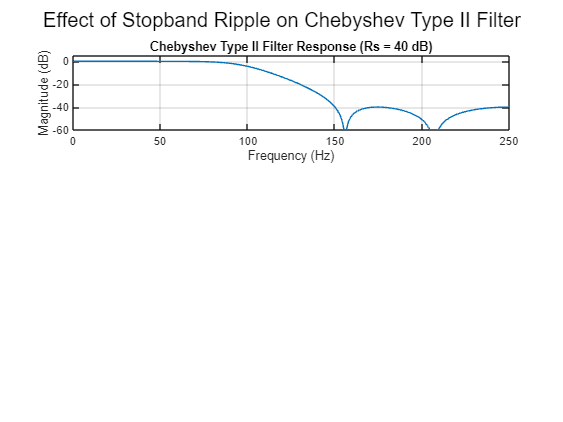

% Parameters needed for cheb filter
Fs = 500;          % Sampling frequency
Fp = 100;           % Passband frequency
Fst = 150;          % Stopband frequency
Rp = 10;             % Passband ripple (dB)

figure;
    sgtitle('Effect of Stopband Ripple on Chebyshev Type II Filter');
    %change Rs values here and on line 19 from 20 to 30 to 40 to find
    %effect of stopband ripple on chebyshex type II filter
    Rs = 40;
    [N, Wn] = cheb2ord(Fp/(Fs/2), Fst/(Fs/2), Rp, Rs);
    [b, a] = cheby2(N, Rs, Wn, 'low');
    
    [H, freq] = freqz(b, a, 512, Fs);
    
    subplot(length(Rs_values), 1,1);
    plot(freq, 20*log10(abs(H)));
    grid on;
    title('Chebyshev Type II Filter Response (Rs = 40 dB)');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    ylim([-60, 5]);